# Two Dimensional Advection Equation

I have had the resutl of one dimension advection equation working, and this made me use the knowledge I got from my previus attempt for this results. So given below are the learning I have got from my previus attempts : 

- The boundary condition has to be imposed on the f_{i-1/2,j} at the left boundary. And similary in nthat case I am aasusming that the flux condition on the walls must be that the f_{i,j-1/2} and f_{1,j+1/2} to be equal; to zero at the boundayr at j = 0 and the j = NY.

- Also the most important suggestion I have got is to use the coarse grid. (Nx = 100, and Ny = 50) rather than Nx = 400, and Ny = 200.

Just with these adjustments I am not going to redo the problem and get the solution with the greensheild's model.

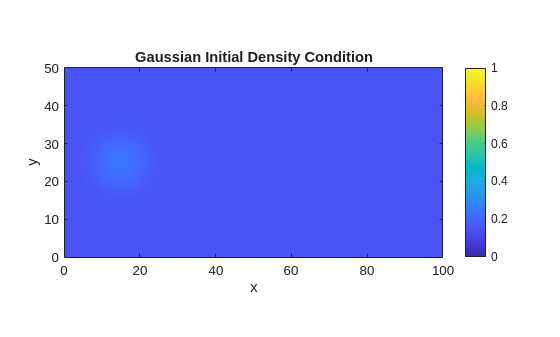

%-------Domain Parameter-----%

% Grid Points
global Nx;
global Ny;
Nx = 100;
Ny = 50;

% Dimension of Domain
Lx = 100;
Ly = 50;

% Domain
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);
[X,Y] = meshgrid(x,y);

% Defining velocity
global x_velocity y_velocity;
x_velocity = 1*ones(Ny,Nx);
y_velocity = 0*ones(Ny,Nx);

% Space Interval
global h;
h = Lx/Nx;

% Total Time
t_total = 120;  

CFL = 0.5;

%-------Initial Condition------%

% First Initial Condition (Gaussian Blob)

xc = 15;    % Center x
yc = 25;    % Center Y
sigma = 5;  % Width
rho_gaussian = 0.1*exp( -((X-xc).^2 + (Y-yc).^2) / (2*sigma^2) ) + 0.15;

% Plotting the Initial Condition
figure(1)
contourf(X,Y,rho_gaussian,'LineStyle', 'none');
title('Gaussian Initial Density Condition');
clim([0,1]);
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

% Function to update X velocity
function x_velocity = makeXvel(rho)
    global x_velocity Nx Ny;
    for i = 1:1:Nx
        for j = 1:1:Ny
            x_velocity(j,i) = 1 - rho(j,i) ;
        end
    end
end

% Function to update Y velocity
function y_velocity = makeYvel(rho)
    global y_velocity Nx Ny;
    for i = 1:1:Nx
        for j = 1:1:Ny
            y_velocity(j,i) = 0;
        end
    end
end

% Function that wil make us the Flux
function flux = makeFlux(rho)

    global Nx Ny;
    global x_velocity
    global y_velocity;

    % Initialzing Flux
    flux_x = zeros(Ny,Nx);
    flux_y = zeros(Ny,Nx);
    flux = zeros(2, Ny, Nx);

    for i = 1:1:Nx
        for j = 1:1:Ny
            flux_x(j,i) = rho(j,i) * x_velocity(j,i);
            flux_y(j,i) = rho(j,i) * y_velocity(j,i);
            flux(1,j,i) = flux_x(j,i);
            flux(2,j,i) = flux_y(j,i);
        end
    end
end

x_velocity = makeXvel(rho_gaussian);
y_velocity = makeYvel(rho_gaussian);


## Time Marching

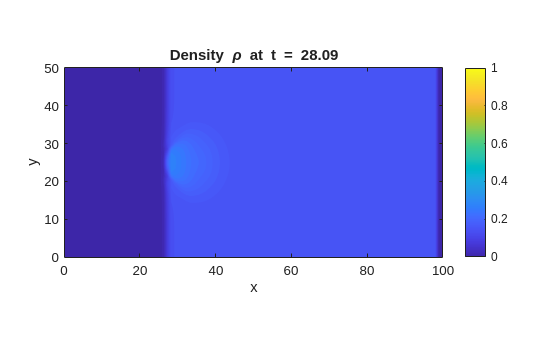

%--Video Capturing--%
video = VideoWriter('two_dimensional_advection_equation.avi', 'Motion JPEG AVI');
video.FrameRate = 20;
open(video);

% Set what kind of initial condition we must be looking at.
rho = rho_gaussian;
rho_max = 1;

%--Preallocating the memory
rho_n = zeros(Ny,Nx);
rho_1 = zeros(Ny,Nx);
rho_2 = zeros(Ny,Nx);
rho_next = zeros(Ny,Nx);

t = 0;

while t< t_total

    % -- Making rho_n and RHS of rho_n
    rho_n = rho;
    semi_discritze_form_rho_n = makeRHS(rho_n);

    %--Update the velocity
    x_velocity = makeXvel(rho_n);
    y_velocity = makeYvel(rho_n);

    % Updating the delta_t with proper CFL condition (Wiki Pedia)
    u_max = max(x_velocity(:));
    dt = CFL / ( u_max/h + 1e-12 );

    % ---------- Makign the RHO_1 and then RHS of rho_1 ------ %
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2
            rho_1(j,i) = rho_n(j,i) + dt * semi_discritze_form_rho_n(j-3,i-3);
        end
    end

    % -- Extrapolation (My Intuition)
    rho_1(:,3) = rho_1(:,4); rho_1(:,2) = rho_1(:,3); rho_1(:,1) = rho_1(:,2); % Right Edge
    rho_1(3,:) = rho_1(4,:); rho_1(2,:) = rho_1(3,:); rho_1(1,:) = rho_1(2,:); % Bottom Edge
    rho_1(Ny-1,:) = rho_1(Ny-2,:); rho_1(Ny,:) = rho_1(Ny-1,:); % Top Edge
    rho_1(:,Ny-1) = rho_1(:,Ny-2); rho_1(:,Ny) = rho_1(:,Ny-1);% Left Edge

    % -- RHS of discritised form using rho_1
    semi_discritze_form_rho_1 = makeRHS(rho_1);

    %--------- Making the RHO_2 and RHS of RHO_2 ----------%
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2
            rho_2(j,i) = 3/4 * rho_n(j,i) + 1/4 * (rho_1(j,i) + dt * semi_discritze_form_rho_1(j-3,i-3));
        end
    end

    % -- Extrapolation (My Intuition)
    rho_2(:,3) = rho_2(:,4); rho_2(:,2) = rho_2(:,3); rho_2(:,1) = rho_2(:,2); % Right Edge
    rho_2(3,:) = rho_2(4,:); rho_2(2,:) = rho_2(3,:); rho_2(1,:) = rho_2(2,:); % Bottom Edge
    rho_2(Ny-1,:) = rho_2(Ny-2,:); rho_2(Ny,:) = rho_2(Ny-1,:); % Top Edge
    rho_2(:,Ny-1) = rho_2(:,Ny-2); rho_2(:,Ny) = rho_2(:,Ny-1); % Left Edge

    % -- RHS of discritised form using rho_2
    semi_discritze_form_rho_2 = makeRHS(rho_2);

    %----------Making the rho_next-------------------------%
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2
            rho_next(j,i) = 1/3 * rho_n(j,i) + 2/3 * (rho_2(j,i) + dt * semi_discritze_form_rho_2(j-3,i-3));
        end
    end

    % -- Extrapolation (My Intuition)
    rho_next(:,3) = rho_next(:,4); rho_next(:,2) = rho_next(:,3); rho_next(:,1) = rho_next(:,2);% Right Edge
    
    rho_next(3,:) = rho_next(4,:); rho_next(2,:) = rho_next(3,:); rho_next(1,:) = rho_next(2,:);% Bottom Edge
    
    rho_next(Ny-1,:) = rho_next(Ny-2,:); rho_next(Ny,:) = rho_next(Ny-1,:);% Top Edge
    
    rho_next(:,Ny-1) = rho_next(:,Ny-2); rho_next(:,Ny) = rho_next(:,Ny-1); % Left Edge


    if mod(round(t/dt),1) == 0
        % ---- 2D contour plot ---- %

        figure(6);
        contourf(x, y, rho_next, 20, 'LineColor', 'none');
        colorbar;
        clim([0 rho_max]);
        title(sprintf('Density \\rho at t = %.2f', t));
        xlabel('x'); ylabel('y');
        axis equal tight;

        drawnow;

        frame = getframe(gcf);
        writeVideo(video, frame);

    end

    t = t + dt;

    % Substituting back the rho value \
    rho = rho_next;
end

close(video);

function semi_discrite_form = makeRHS(rho)

    global Nx Ny x_velocity y_velocity h;
    semi_discrite_form = zeros(Ny-77,Nx-5);

    %--Flux for the given rho distribution
    flux = makeFlux(rho);
    flux_x = squeeze(flux(1,:,:));
    flux_y = squeeze(flux(2,:,:));

    % Calculating the maximum speed
    alpha_x = max(abs(x_velocity(:)));
    alpha_y = max(abs(y_velocity(:)));

    % -- Calculating the value of f+ and f- at {i+2,i+1,i,i-1,i-2,i-3} -- %
    fx_negative_whole = zeros(Ny,Nx);
    fx_positive_whole = zeros(Ny,Nx);
    fy_negative_whole = zeros(Ny,Nx);
    fy_positive_whole = zeros(Ny,Nx);

    fx_negative_half = zeros(Ny-5,Nx-5);
    fx_positive_half = zeros(Ny-5,Nx-5);
    fy_negative_half = zeros(Ny-5,Nx-5);
    fy_positive_half = zeros(Ny-5,Nx-5);

    for j = 1:1:Ny
        for i=1:1:Nx
        fx_positive_whole(j,i) = 1/2 * (flux_x(j,i) + alpha_x*rho(j,i));
        fx_negative_whole(j,i) = 1/2 * (flux_x(j,i) - alpha_x*rho(j,i));
        fy_positive_whole(j,i) = 1/2 * (flux_y(j,i) + alpha_y*rho(j,i));
        fy_negative_whole(j,i) = 1/2 * (flux_y(j,i) - alpha_y*rho(j,i));
        end
    end

    % -- Computing the RHS of Semi Discrite form.
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2

            %--X--%
            % fx{+}_[i+1/2,j]
            fx_plus_x_half_forward = stencil( ...
                fx_positive_whole(j,i-2), ...
                fx_positive_whole(j,i-1), ...
                fx_positive_whole(j,i), ...
                fx_positive_whole(j,i+1), ...
                fx_positive_whole(j,i+2));

            % fx{+}_[i-1/2,j]
            fx_plus_x_half_backward = stencil( ...
                fx_positive_whole(j,i-3), ...
                fx_positive_whole(j,i-2), ...
                fx_positive_whole(j,i-1), ...
                fx_positive_whole(j,i), ...
                fx_positive_whole(j,i+1));
            
            % fx{-}_[i+1/2,j]
            fx_minus_x_half_forward = stencil( ...
                fx_negative_whole(j,i+2), ...
                fx_negative_whole(j,i+1), ...
                fx_negative_whole(j,i), ...
                fx_negative_whole(j,i-1), ...
                fx_negative_whole(j,i-2));

            % fx{-}_[i-1/2,j]
            fx_minus_x_half_backward = stencil( ...
                fx_negative_whole(j,i+1), ...
                fx_negative_whole(j,i), ...
                fx_negative_whole(j,i-1), ...
                fx_negative_whole(j,i-2), ...
                fx_negative_whole(j,i-3));

            %--Y--%
            % fy{+}_[i,j+1/2]
            fy_plus_y_half_forward = stencil( ...
                fy_positive_whole(j-2,i), ...
                fy_positive_whole(j-1,i), ...
                fy_positive_whole(j,i), ...
                fy_positive_whole(j+1,i), ...
                fy_positive_whole(j+2,i));

            % fy{+}_[i,j-1/2]
            fy_plus_y_half_backward = stencil( ...
                fy_positive_whole(j-3,i), ...
                fy_positive_whole(j-2,i), ...
                fy_positive_whole(j-1,i), ...
                fy_positive_whole(j,i), ...
                fy_positive_whole(j+1,i));

            % fy{-}_[i,j+1/2]
            fy_minus_y_half_forward = stencil( ...
                fy_negative_whole(j+2,i), ...
                fy_negative_whole(j+1,i), ...
                fy_negative_whole(j,i), ...
                fy_negative_whole(j-1,i), ...
                fy_negative_whole(j-2,i));
            
            % fy{-}_[i,j-1/2]
            fy_minus_y_half_backward = stencil( ...
                fy_negative_whole(j+1,i), ...
                fy_negative_whole(j,i), ...
                fy_negative_whole(j-1,i), ...
                fy_negative_whole(j-2,i), ...
                fy_negative_whole(j-3,i));

            fx_positive_half = fx_plus_x_half_forward + fx_minus_x_half_forward;
            fx_negative_half = fx_plus_x_half_backward + fx_minus_x_half_backward;
            fy_positive_half = fy_plus_y_half_forward + fy_minus_y_half_forward;
            fy_negative_half = fy_plus_y_half_backward + fy_minus_y_half_backward;

            %--Boundary Condition -- %

            % Left Wall (Flux set to Zero)
            if(i == 4)
                fx_negative_half = 0;
            elseif(j==0)
                fy_negative_half = 0;
            elseif(j == Ny-2)
                fy_positive_half = 0;
            end

            % Computing RHS of Semi Discritized form
            semi_discrite_form(j-3,i-3) = - 1/h * (fx_positive_half - fx_negative_half) - 1/h * (fy_positive_half - fy_negative_half);
        end
    end
end


% To compute f half. Order of input matters
function f = stencil(f1,f2,f3,f4,f5)

    eta = 10^-6;

    % Compute S values
    s_1 = ((1/3) * f1) + ((-7/6) * f2) + ((11/6) * f3);
    s_2 = ((-1/6) * f2) + ((5/6) * f3) + ((1/3) * f4);
    s_3 = ((1/3) * f3) + ((5/6) * f4) + ((-1/6) * f5);

    % Compute Beta
    beta_1 = 13/12 * (f1 - 2*f2 + f3)^2 + 1/4 * (f1 - 4*f2 + 3*f3)^2;
    beta_2 = 13/12 * (f2 - 2*f3 + f4)^2 + 1/4 * (f2 - f4)^2;
    beta_3 = 13/12 * (f3 - 2*f4 + f5)^2 + 1/4 * (3*f3 - 4*f4 + f5)^2;

    % Definign Gamma
    gamma_1 = 1/10;
    gamma_2 = 3/5;
    gamma_3 = 3/10;
    
    % Computing weights bar
    w_1_dash = ( gamma_1 ) / ((eta + beta_1)^2);
    w_2_dash = ( gamma_2 ) / ((eta + beta_2)^2);
    w_3_dash = ( gamma_3 ) / ((eta + beta_3)^2);

    % Computing Weights
    w_1 = ( w_1_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_2 = ( w_2_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_3 = ( w_3_dash ) / (w_1_dash + w_2_dash + w_3_dash);

    % Computing Flux
    f = w_1 * s_1 + w_2 * s_2 + w_3 * s_3;
end